syms phi t real
syms P_max_ratio positive
assumeAlso(P_max_ratio<=1)

P_avg = 1/2 * cos(phi);
assumeAlso(P_avg > 0)

P_unsat = P_avg + 1/2 * cos(2*t - phi);
P_max = P_avg + 1/2 * P_max_ratio;
P_min = -P_max;

t1 = 1/2*acos(P_max_ratio) + phi/2;
t2_formula = phi/2 + sym(pi/2) - 1/2*acos(2*(P_avg-P_min));
t2  = piecewise(P_min > P_avg-1/2, t2_formula, phi/2+sym(pi/2));

term1 = int(P_max,   t, phi/2, t1);
term2a = int(P_unsat,t, t1,  phi/2+pi/4);
term2b = int(P_unsat,t, phi/2+pi/4, t2);
term3 = int(P_min,   t, t2,  phi/2+pi/2);

P_int = term1 + term2a + term2b + term3;

P_avg_sat = P_int / (pi/2);
ratio = P_avg_sat / P_avg

$$ratio = \begin{array}{l} \left\{ \begin{array}{cl} \frac{4\,\left(\sigma_{3}-\frac{\mathrm{acos}\left(\sigma_{2}\right)\,\left(P_{\max,\mathrm{ratio}}+\cos\left(\varphi \right)\right)}{4}+\sigma_{1}+\frac{\sqrt{1-{\sigma_{2}}^{2}}}{4}-\sigma_{4}+\cos\left(\varphi \right)\,\left(\frac{\pi }{8}-\frac{\mathrm{acos}\left(\sigma_{2}\right)}{4}\right)\right)}{\pi \,\cos\left(\varphi \right)} & \text{ if }\sigma_{2}<1\\ \frac{4\,\left(\sigma_{3}+\sigma_{1}+\frac{\pi \,\cos\left(\varphi \right)}{8}-\sigma_{4}\right)}{\pi \,\cos\left(\varphi \right)} & \mathrm{otherwise} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{acos}\left(P_{\max,\mathrm{ratio}}\right)\,\left(\frac{P_{\max,\mathrm{ratio}}}{2}+\frac{\cos\left(\varphi \right)}{2}\right)}{2}\\ \sigma_{2}=P_{\max,\mathrm{ratio}}+2\,\cos\left(\varphi \right)\\ \sigma_{3}=\cos\left(\varphi \right)\,\left(\frac{\pi }{8}-\frac{\mathrm{acos}\left(P_{\max,\mathrm{ratio}}\right)}{4}\right)\\ \sigma_{4}=\frac{\sqrt{1-{P_{\max,\mathrm{ratio}}}^{2}}}{4} \end{array}$$


ratio = simplify(expand(ratio))

$$ratio = \begin{array}{l} \left\{ \begin{array}{cl} \frac{P_{\max,\mathrm{ratio}}\,\mathrm{acos}\left(P_{\max,\mathrm{ratio}}\right)-2\,\mathrm{acos}\left(\sigma_{1}\right)\,\cos\left(\varphi \right)+\pi \,\cos\left(\varphi \right)-\sigma_{2}+\sqrt{-{P_{\max,\mathrm{ratio}}}^{2}-4\,P_{\max,\mathrm{ratio}}\,\cos\left(\varphi \right)-4\,{\cos\left(\varphi \right)}^{2}+1}-P_{\max,\mathrm{ratio}}\,\mathrm{acos}\left(\sigma_{1}\right)}{\pi \,\cos\left(\varphi \right)} & \text{ if }\sigma_{1}<1\\ \frac{P_{\max,\mathrm{ratio}}\,\mathrm{acos}\left(P_{\max,\mathrm{ratio}}\right)+\pi \,\cos\left(\varphi \right)-\sigma_{2}}{\pi \,\cos\left(\varphi \right)} & \mathrm{otherwise} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=P_{\max,\mathrm{ratio}}+2\,\cos\left(\varphi \right)\\ \sigma_{2}=\sqrt{1-{P_{\max,\mathrm{ratio}}}^{2}} \end{array}$$

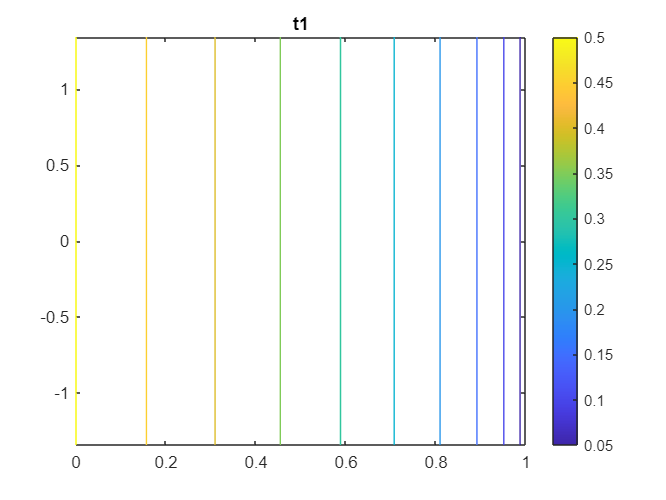


fcontour((t1-phi/2)/(pi/2),[0 1 -3*pi/7 3*pi/7])
title('t1')
colorbar

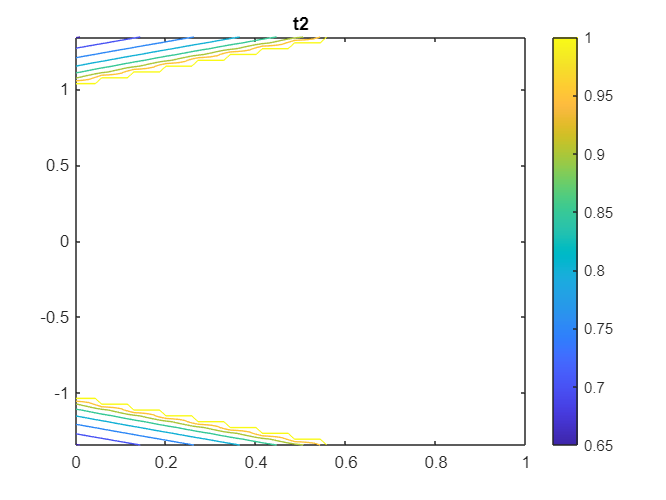

fcontour((t2-phi/2)/(pi/2),[0 1 -3*pi/7 3*pi/7])
title('t2')
colorbar

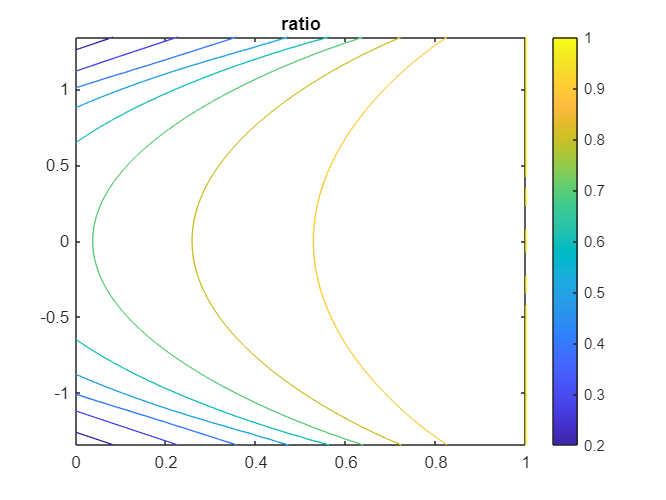

fcontour(ratio,[0 1 -3*pi/7 3*pi/7])
title('ratio')
colorbar

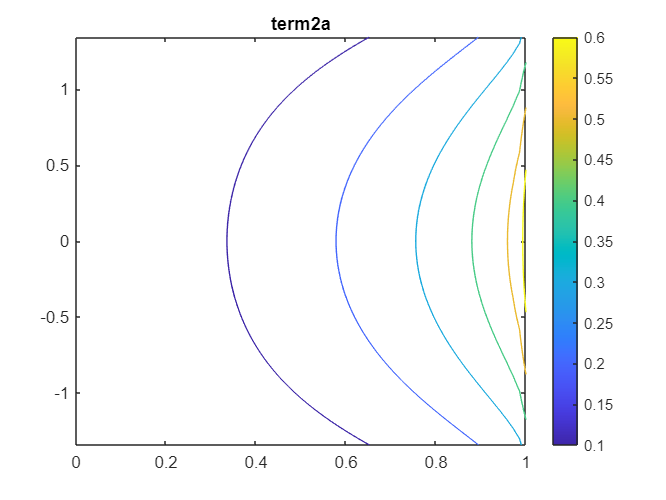

fcontour(term2a,[0 1 -3*pi/7 3*pi/7])
title('term2a')
colorbar

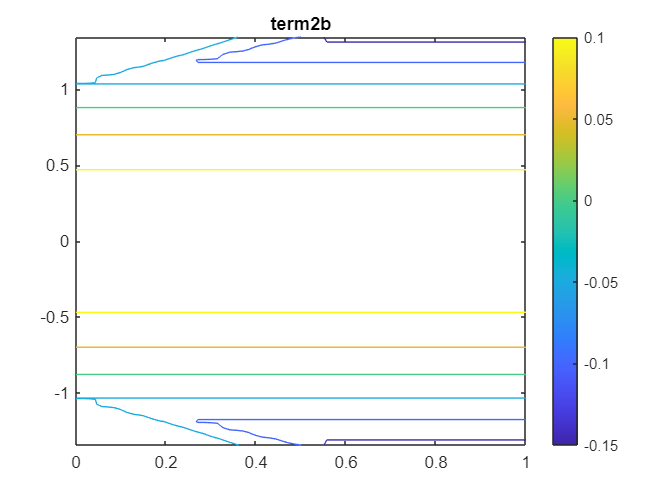

fcontour(term2b,[0 1 -3*pi/7 3*pi/7])
title('term2b')
colorbar


matlabFunction(ratio,'File','simulation/modules/dynamics/power_saturation_ratio','Vars',[P_max_ratio,phi],'Outputs',{'P_avg_sat_over_P_avg_unsat'})

ans = function_handle with value:
    @power_saturation_ratio
